#### Set up

load('amsr_n3125_Arctic_m03_y2025-v5.4.mat');
addpath("E:\University\EngSci Thesis\Thesis work\external\m_map");

month = month_ts(1);
day = 12;
year = year_ts(1);

#### Parameters

%% seaice concentration of the day to be studied 2D matrix
seaice = double(squeeze(seaice_ts(day,:,:)));

%% Define the polynya region of interest (ROI),
lat_min = 70; 
lat_max = 70.5;
lon_min = -24;
lon_max = -21;

%% Linear array of indices of the matrix cells that represents a point in polynya
polynya_roi = find(lat>=lat_min & lat<=lat_max & lon >= lon_min & lon <= lon_max);

#### Stereographic Projection of Sea Ice Concentration data

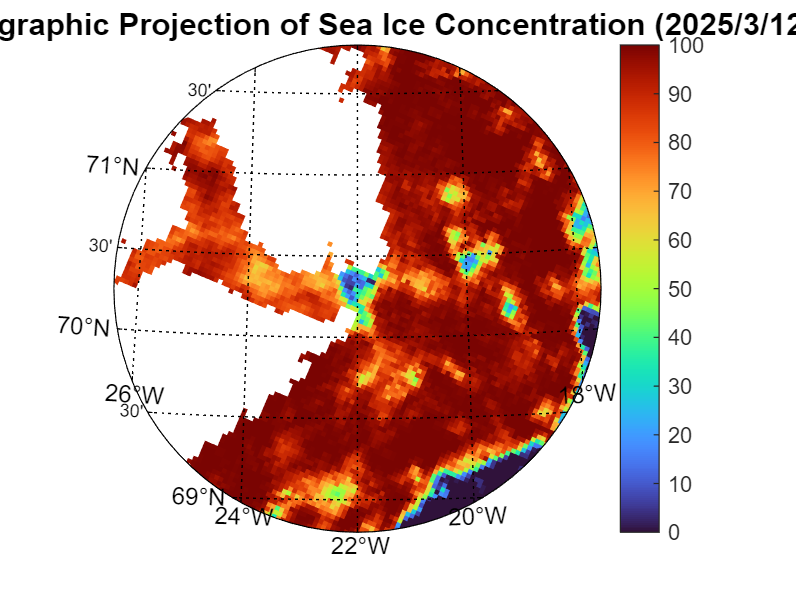

figure('Color','w');
hold on;

% Set up polar stereographic projection
m_proj('stereographic', 'lat', 70.3, 'long', -22, 'rad', 1.5);

% Overlay sea ice concentration
m_pcolor(lon, lat, seaice);
colormap("turbo");
clim([0 100]);
colorbar;
title_string = sprintf('Stereographic Projection of Sea Ice Concentration (%u/%u/%u)', year, month, day);
title(title_string, 'FontSize', 13);

% Add coastlines
% m_coast;    % The most basic coastline resolution is used
m_grid;

hold off;

#### Showing Polynya ROI

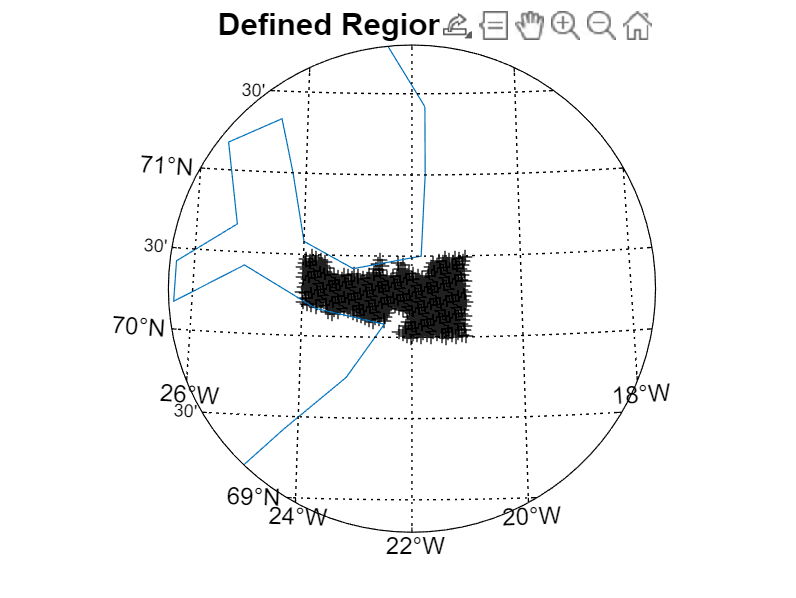

figure('Color','w');
hold on;

% Set up polar stereographic projection
m_proj('stereographic', 'lat', 70.3, 'long', -22, 'rad', 1.5);


%%%% Optional: Underlay sea ice concentration
% m_pcolor(lon, lat, squeeze(seaice_ts(day,:,:)));
% colormap("turbo");
% clim([0 100]);
% colorbar;

%%%% Identify regions
for i = polynya_roi(:)'  % Loop through each point in polynya
    if ~isnan(seaice(i))        % plot the point, if it does not correspond to land
        m_plot(lon(i), lat(i), '+', 'Color', 'k');
    end
end
title('Defined Region of Interest', 'FontSize', 13);

% Add coastlines
m_coast;    % The most basic coastline resolution is used
m_grid;

hold off;

#### Calculating Area of Open Water

Area of open water per cell (AOW_i) = (100 - ice_concentration)/100 × 3.125 km²

addpath("E:\University\EngSci Thesis\Thesis work\functions");

aow = calcOpenWater(lon, lat, [70, 70.5], [-24, -21])

aow = 0


% Initialize counter for area of open water
% aow=0;
% for i = polynya_roi(:)'  % Loop through each point in polynya
%     if ~isnan(seaice(i))        % plot the point, if it does not correspond to land
%         aow_i = (100-seaice(i))/100 * 3.125;
%         aow = aow + aow_i;
%     end
% end
% 
% disp(aow)